# Acceleration

Le script suivant permet de simuler une acceleration sur une distance donnée. De nombreuses ameliorations peuvent etre apportees par la suite. Ce script est utile pour voir l'influence des differents parametres sur le temps de l'acceleration

## Hypotheses

- Le pneu est indeformable

- Le coeff de résistance au roulement est constant

- Le transfert de charge est instantane

- Les pertes dans la transmission sont proportionnelles au couple

- L'appui est neglige

- La trainée est celle d'invictus

## Parametres

% clear all
% close all

g = 9.81; % Pesanteur (m/s²)

% Epreuve et pilotage
D_tot = 75; % Longueur de la piste (m)
m_p = 75; % Masse du pilote (kg)
h_g_p = 0.42; % Hauteur du centre de gravite du pilote (m)

% Transmission
k_p =[0.1:1/200:0.5]; % Rapport transmission
pertes = 0.95; % Coefficient de pertes de couple dans la transmission

% Pneumatiques
% Pas de glissement
coeff_adh = 1.55;
coeff_roul = 0.01; % Coefficient de resistance au roulement du pneu
sl=0;

% Base roulante
cx=0.665;%coefficient de trainée
m_v = 222; % Masse du vehicule (kg)
h_g_v = 0.3; % Hauteur du centre de gravite de la voiture (m)
emp = 1.575; % Empattement (m)
rep = 0.55; % Masse sur l'essieu arrière en statique (%)
D_roue = 0.52; % Diametre exterieur de la roue (m)
Jjp = 0.3046 ; %Inertie de la roue et du pneu (CATIA)
Jm = 0.005; %Inertie du moyeu et du freinage (CATIA)
Ja = 0; %inertie d'un arbre de transmission  (CATIA)
Jc = 0.005; % Inertie de la couronne (CATIA)
Jmot = 0.1; % Estimation de l'inertie moteur+ chaine
m = m_v + m_p; % Masse totale (kg)
h_g = (m_v*h_g_v+m_p*h_g_p)/m; % Hauteur du centre de gravite (m)
b = coeff_roul*2/D_roue; % Decalage du point d'appui (m)
c_roul = m*g*b; % Resistance au roulement (N.m)


%Moteur emrax 90 N.m
trmax=5500; %tr/min rupteur
cmot=230; %N.m


## Simulation

Théorème énergie puissance


$$\frac{dE_{\textrm{ctot}} }{\textrm{dt}}=\sum P_{\textrm{ext}} +P_{\int }$$



$$E_{\textrm{cmot}} +E_{\textrm{ctransmission}} +E_{\textrm{cvéhicule}} =E_{\textrm{ctot}}$$



$$\frac{1}{2}J_{\textrm{mot}} {\omega_{\textrm{mot}} }^2 +\frac{1}{2}J_{\textrm{trans}} {\omega_{\textrm{trans}} }^2 +\frac{1}{2}{\textrm{mv}}^2 =\frac{1}{2}\left(J_{\textrm{mot}} +J_{\textrm{trans}} {*K}_p^2 +m*K_p^2 *\frac{\phi_{\textrm{roue}} }{2}\right)*\omega_{\textrm{mot}}$$



$$\left(J_{\mathrm{mot}} +J_{\mathrm{trans}} {*K}_p^2 +m*K_p^2 *\frac{\phi_{\mathrm{roue}} }{2}\right)*\omega_{\mathrm{mot}} *\frac{d\omega_{\mathrm{mot}} }{\mathrm{dt}}=C_{\mathrm{mot}} *\omega_{\mathrm{mot}} -C_{\mathrm{roul}} *\omega_{\mathrm{roue}} -F_{\mathrm{trainée}} *v$$



$$\left(J_{\textrm{mot}} +J_{\textrm{trans}} {*K}_p^2 +m*K_p^2 *\frac{\phi_{\textrm{roue}} }{2}\right)\frac{d\omega_{\textrm{mot}} }{\textrm{dt}}=C_{\textrm{mot}} -C_{\textrm{roul}} *\textrm{Kp}-F_{\textrm{trainée}} *\textrm{Kp}*\frac{\phi_{\textrm{roue}} }{2}$$


- 
$$\omega_{\textrm{trans}} =\textrm{Kp}*\omega_{\textrm{mot}}$$


- 
$$v=\frac{\phi_{\textrm{roue}} }{2}*\omega_{\textrm{trans}}$$


- 
$$C_{\textrm{mot}} =150\;\textrm{Nm}:\textrm{Couple}\;\textrm{fournit}\;\textrm{par}\;\textrm{le}\;\textrm{moteur}$$


- 
$$C_{\textrm{roul}} =\textrm{mg}*{\textrm{coeff}}_{\textrm{adh}} *\frac{2}{\phi_{\textrm{roue}} }:\textrm{Couple}\;\textrm{perdue}\;\textrm{par}\;\textrm{roulement}$$


- $F_{\textrm{trainée}} =c_x *v^2$: Force de trainée


% Paramètres simulation
Trapport=[];
pas = 0.001; % Pas de simulation (s)
A = [0]; % Acceleration en g
for i =1:length(k_p);
    % Initialisation
    d = 0; % distance parcourue
    r = 0; % regime moteur au depart
    v = 0; % vitesse du vehicule
    t = -pas; % temps
    T = [0]; % Temps
    V = [0]; % Vitesse
    a = 0; %acceleration instantannée
    amax=0;
    R = [0]; % Regime
    C = [0]; % Couple
    D = [0]; % Distance
    T_pas = [];
    Adh = [1]; % Risque de patinage des pneus
    Ch_ar = [rep*m*g];
    Kp=k_p(i);
    J_eq = Jmot+Kp^2*(Ja+2*Jc+2*Jjp)+m_v*Kp^2*(D_roue/2)^2; % Inertie equivalente des masses en rotation(kg.m²)
    c_trans = coeff_adh*m*g*rep*D_roue/2; % Couple maximum transmissible   
    while d < D_tot
        t = t+pas; 
        T = [T t];
        tr = 60*v/(3.14*D_roue*Kp); % Calcul du regime moteur
        
        % Acceleration
        if tr<trmax & cmot<c_trans; %condition de non patinage et de respect de la plage de puissance du moteur
            c_k=cmot;
            a_ang = (c_k-c_roul*Kp-cx*v^2*D_roue/2*Kp)/J_eq; % Acceleration angulaire des roues arrieres
            c_trans = coeff_adh*m*g*D_roue/2*(rep+a*h_g); % Couple maximum transmissible avec transfert de charges 
            a = (1-sl)*a_ang*Kp*D_roue/2; % Acceleration du vehicule en m/s²
            
        elseif tr>=trmax;
            tr=trmax;
            a_ang=0;
            a=0;
        else;
            c_k = c_trans*Kp; % Prise en compte de la limite d'adherence des pneus
            a_ang = (c_k-c_roul*Kp-cx*v^2*D_roue/2*Kp)/J_eq; % Acceleration angulaire des roues arrieres
            c_trans = coeff_adh*m*g*D_roue/2*(rep+a*h_g); % Charge sur l'essieu arrière avec prise en compte du transfert de masse
            a = (1-sl)*a_ang*Kp*D_roue/2; % Acceleration du vehicule en m/s²
            
        end
    
        v = v + a*pas; % Vitesse du vehicule
        V = [V v]; % Memoire de la vitesse
        d = d + v*pas; % Distance parcourue
        D = [D, d]; % Memoire de la distance
        tr = v/D_roue*60/3.14/Kp; % Calcul du regime moteur
        if a>amax
            amax=a;
        end
        
        
    end
    Trapport=[Trapport, t];
    A=[A amax];
end

## Principaux resultats

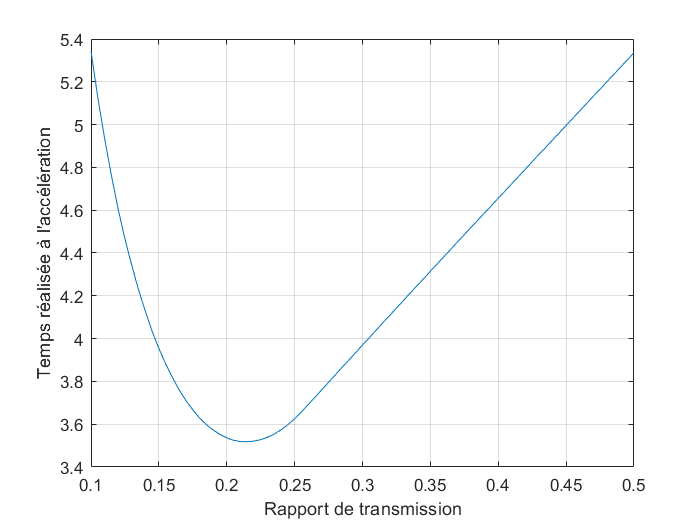

figure('Name','Choix du rapport de transmission')
plot(k_p,Trapport)
grid()
xlabel('Rapport de transmission');
ylabel("Temps réalisée à l'accélération");

disp('Temps (s) :')

Temps (s) :


disp(min(Trapport))

    3.5180



disp('Vitesse max (km/h) :')

Vitesse max (km/h) :


disp(max(V)*3.6)

   94.6391



disp('Acceleration max (g) :')

Acceleration max (g) :


disp(max(A)/g)

    2.2628



if max(Ch_ar) == m*g
    disp('Wheeliiiinnngg ! :p')
end
disp('---------------------------------------------------------')

---------------------------------------------------------
